# Controlador de páncreas artificial

Tenemos un páncreas artificial que regula el nivel de glucosa de un individuo con diabetes tipo 1 utilizando infusión subcutánea de insulina. La diabetes tipo 1 es un problema de salud que ocurre cuando el páncreas no puede producir suficiente insulina para regular los niveles de glucosa. Si no se controlan los niveles altos de glucosa (hiperglucemia) se pueden originar problemas graves en el organismo como deshidratación o un aumento en la probabilidad de ictus o de infarto de miocardio. Un sistema de páncreas artificial permite monitorear los niveles de glucosa y administrar dosis de insulina cuando sea necesario.

Un diagrama de un sistema de páncreas artificial se muestra a continuación:

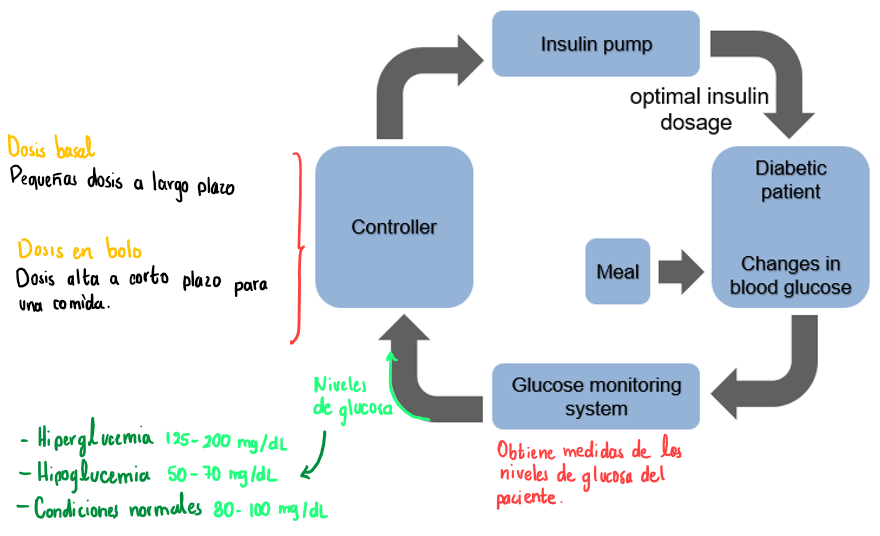

El contronlador proporcionará una de dos dosis de insulina:

- **Basal**: largo plazo en dosis pequeñas.

- **En bolo**: corto plazo en dosis altas.

Como entradas a nuestro controlador, tenemos los siguientes casos:

- **Hiperglucemia**: cuando hay una alta concentración de glucosa (125 - 200 mg/dL), entonces el controlador debe suministrar dosis de insulina en bolo.

- **Hipoglucemia**: cuando hay una baja concentración de glucosa (50 - 70 mg/dL), entonces el controlador deja de suministrar insulina.

- **Condiciones normales**: Los niveles de glucosa son generalmente de 80 - 100 mg/dL, entonces el controlador suministra insulina en dosis basal.

## Modelo en Simulink

En Matlab se encuentra un modelo en Simulink del sistema anterior, podemos acceder a él con el nombre `artificialPancreasWithFISTreeControl.`

model = 'artificialPancreasWithFISTreeControl';
load_system(model)

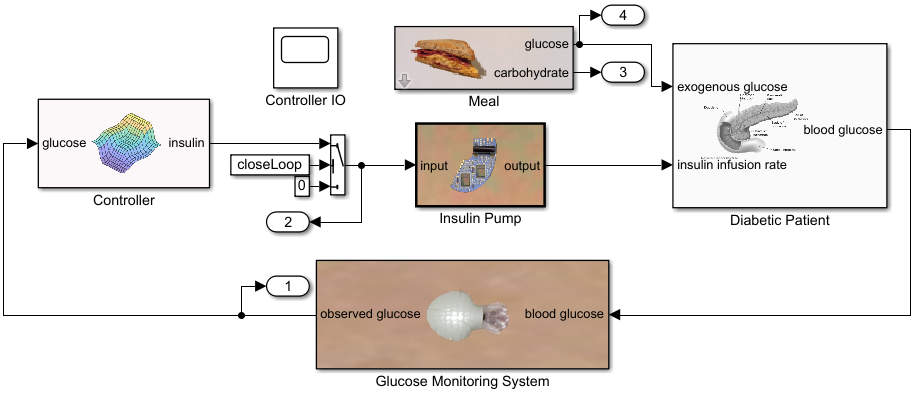

Podemos observar el comportamiento de los niveles de glucosa simulando nuestro modelo.

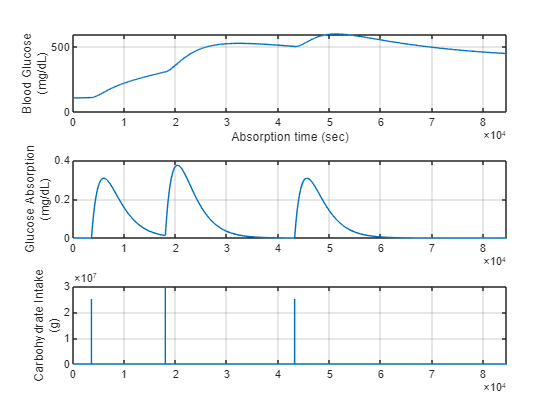

closeLoop = 0;
openLoopOutput = sim(model);
plotAbsorbedAndBloodGlucose(openLoopOutput);

% Cerramos el Loop para simulacion
closeLoop = 1;

## FIS

El controlador tiene las siguientes entradas:

- Nivel de glucosa en sangre (mg/dL).

- Tasa de cambio del nivel de glucosa en sangre (mg/dL/min).

- Aceleración del nivel de glucosa en sangre (mg/dL/min/min).

El controlador del modelo de Simulink utiliza un sistema experto con 75 reglas. Por lo que en este ejemplo utilizaremos un árbol difuso, disminuyendo el número de reglas y mejorando la comprensión del controlador.

El nivel de glucosa y su tasa de cambio son factores más importantes que la aceleración, por lo que utilizaremos estas dos entradas en un primer nivel de nuestro árbol difuso con estructura incremental. Entonces nuestro árbol tendrá la siguiente estructura:

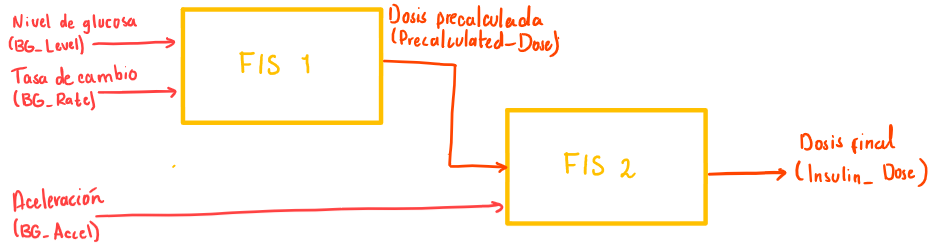

### FIS1

Para nuestro primer FIS, tenemos las siguientes entradas y salida con sus respectivos términos:

- `BG_Level`: puede ser bajo, medio o alto (`L, M, H`).

- `BG_Rate`: puede ser negativa, positiva o cero (`P, N, Z`).

- `Precalculated_Dose`: puede ser muy baja, baja, media, alta o muy alta (`VL, L, M, H, VH`).

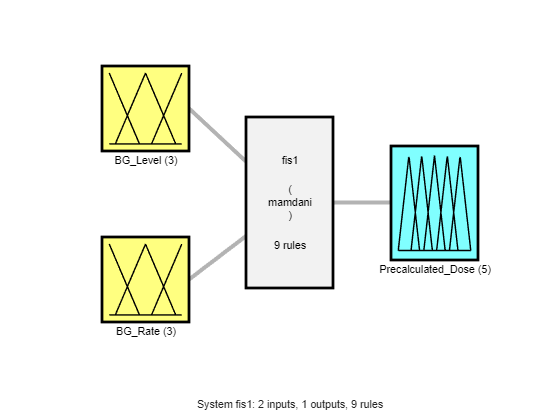

% Nivel máximo de dosis
maxDose = 2;

% Nombres de las funciones de membresia de entrada
mfNames1 = ["L","M","H"]; % Bajo, Medio, Alto
mfNames2 = ["N","Z","P"]; % Negativo, Cero, Positivo

% Creamos fis1 tipo Mamdani, damos 5 MF de salida
fis1 = mamfis('Name','fis1','NumInputs',2,'NumOutputs',1, ...
    'NumInputMFs',3,'NumOutputMFs',5);

% Configuramos las entradas y salidas.
fis1 = updateInput(fis1,1,'BG_Level',[80 120],mfNames1);
fis1 = updateInput(fis1,2,'BG_Rate',[-0.5 0.5],mfNames2);
fis1 = updateOutput(fis1,1,'Precalculated_Dose',[0 maxDose]);

figure;
plotfis(fis1)

### FIS2

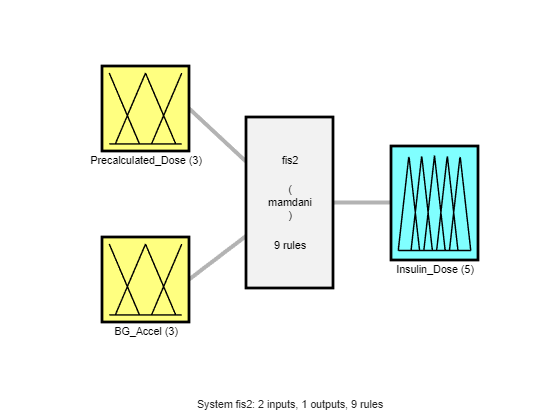

% Creamos el segundo FIS.
fis2 = mamfis('Name','fis2','NumInputs',2,'NumOutputs',1, ...
    'NumInputMFs',3,'NumOutputMFs',5);

% Configuramos las salidas y entradas del FIS.
fis2 = updateInput(fis2,1,'Precalculated_Dose',[0 maxDose],mfNames1);
fis2 = updateInput(fis2,2,'BG_Accel',[-0.005 0.005],mfNames2);
fis2 = updateOutput(fis2,1,'Insulin_Dose',[0 maxDose]);

figure
plotfis(fis2)

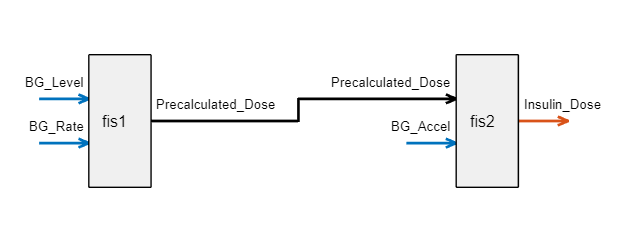

% Creamos las conexiones y creamos el arbol difuso
connection = [fis1.Name + "/" + fis1.Outputs(1).Name ...
    fis2.Name + "/" + fis2.Inputs(1).Name];
fisTInit = fistree([fis1 fis2],connection);

figure
plotfis(fisTInit)

## Optimización de las reglas

Ahora utilizamos la función `tunefis` para optimizar las reglas.

% Obtenemos los parametros optimizables
[in,out,rule] = getTunableSettings(fisTInit);

% Ahora hacemos que los antecedentes no puedan optimizarse, ya que ya
% tenemos todas las combinaciones y no queremos que se modifiquen.
for rId = 1:numel(rule)
    rule(rId).Antecedent.Free = false;
end

% Objeto de opciones para optimizar usando un algoritmo genetico
options = tunefisOptions('Method', 'ga');
options.MethodOptions.MaxGenerations = 3;
options.MethodOptions.PopulationSize = 100;

Ahora utilizaremos una función de costo personalizada `costFcn`, la cual evalúa nuestro FIS siguiendo los pasos:

- Calcula los errores usando un valor nominal de niveles de glucosa.

- Si el error es negativo (niveles de glucosa menores al valor nominal), entonces asignamos un valor alto.

- Calculamos el error medio cuadrático.

Con esto, estamos evaluando que el controlador mantenga normales los niveles de glucosa, además penalizamos que esté debajo del valor nominal para descartar todos los FIS que tengan este comportamiento. En resumen sigue el siguiente pseudocódigo:

El proceso de optimización puede tardar mucho tiempo, por lo que utilizamos un arbol pre-optimizado.

% Arbol difuso pre entrenado
data = load('fuzzyPancreasExampleData.mat');

minData = MinCostData;
wsVars = ["fisT" "closeLoop"];
minLevel = 80;
refLevel = 90;

% Si se quiere realizar el entrenamiento ejecutar el siguiente codigo
% (puede tardar)
% rng('default')
% fisTRuleTuned = tunefis(fisTInit,rule,...
%     @(fis)costFcn(fis,model,minLevel,refLevel,wsVars,minData),options);

fisTRuleTuned = data.fisTRuleTuned;
% Mostramos el costo de nuestro arbol difuso
minCost = costFcn(fisTRuleTuned,model,minLevel,refLevel,wsVars)

minCost = 26.3335

Ahora simulamos nuestro arbol difuso que hasta ahora sólo ha aprendido las reglas difusas.

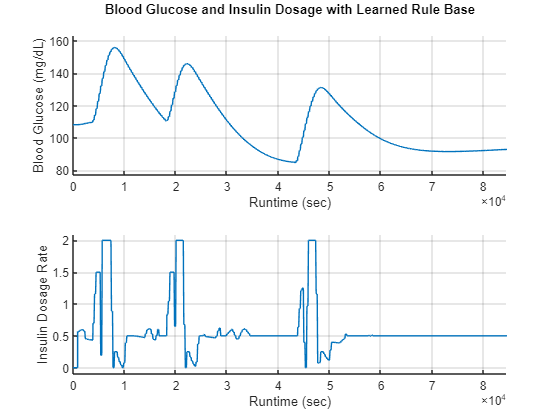

fisT = fisTRuleTuned;
ruleTunedOutput = sim(model);

% Mostramos los niveles de glucosa y dosis de insulina
plotGlucoseAndInsulin(ruleTunedOutput,...
    'Blood Glucose and Insulin Dosage with Learned Rule Base')

### Modicación de las reglas

Podemos observar las superficies de control de nuestros FIS.

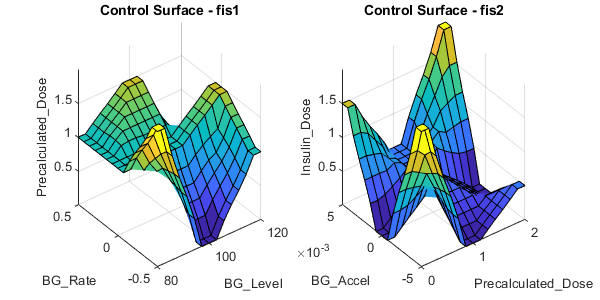

figure('Position',[300 300 600 300]);
subplot(1,2,1)
gensurf(fisTRuleTuned.FIS(1))
title('Control Surface - fis1')
subplot(1,2,2)
gensurf(fisTRuleTuned.FIS(2))
title('Control Surface - fis2')

Podemos observar las reglas generadas por el algoritmo utilizado anteriormente.

showRuleBase(fisTRuleTuned.FIS(1))

Rule base of fis1:
                         BG_Rate: N               BG_Rate: Z                BG_Rate: P      
                   ______________________    _____________________    ______________________

    BG_Level: L    Precalculated_Dose: VH    Precalculated_Dose: M    Precalculated_Dose: M 
    BG_Level: M    Precalculated_Dose: VL    Precalculated_Dose: M    Precalculated_Dose: H 
    BG_Level: H    Precalculated_Dose: M     Precalculated_Dose: H    Precalculated_Dose: VL



showRuleBase(fisTRuleTuned.FIS(2))

Rule base of fis2:
                               BG_Accel: N         BG_Accel: Z         BG_Accel: P   
                             ________________    ________________    ________________

    Precalculated_Dose: L    Insulin_Dose: VH    Insulin_Dose: VL    Insulin_Dose: H 
    Precalculated_Dose: M    Insulin_Dose: VL    Insulin_Dose: L     Insulin_Dose: L 
    Precalculated_Dose: H    Insulin_Dose: L     Insulin_Dose: VL    Insulin_Dose: VH



Algunas de las acciones de control no son intuitivas, por ejemplo, tenemos:

- Si la tasa es negativa, el sistema no incrementa la dosis de forma lógica de acuerdo con los niveles de glucosa, esto ocurre en ambos fis.

- Para un nivel alto de glucosa y una tasa positiva, en `fis1` no tenemos que la dosis deba ser muy alta.

- Para una dosis precalculada baja y una aceleración negativa, `fis2` nos dice que debe suministrarse una dosis muy alta en lugar de un nivel bajo.

- Para una dosis precalculada alta y con aceleración cero, `fis2` nos dice que debe suministrarse una dosis muy baja en lugar de un nivel medio.

Podemos reescribir algunas de estas reglas y actualizar nuestro FIS.

% Actualizamos las reglas de fis1.
fisTRuleUpdate = fisTRuleTuned;
fisTRuleUpdate.FIS(1).Rules(1).Description = ...
    "BG_Level==L & BG_Rate==N => Precalculated_Dose=VL";
fisTRuleUpdate.FIS(1).Rules(2).Description = ...
    "BG_Level==M & BG_Rate==N => Precalculated_Dose=M";
fisTRuleUpdate.FIS(1).Rules(3).Description = ...
    "BG_Level==H & BG_Rate==N => Precalculated_Dose=H";
fisTRuleUpdate.FIS(1).Rules(9).Description = ...
    "BG_Level==H & BG_Rate==P => Precalculated_Dose=VH";

% Actualizamos las reglas de fis2.
fisTRuleUpdate.FIS(2).Rules(1).Description = ...
    "Precalculated_Dose==L & BG_Accel==N => Insulin_Dose=VL";
fisTRuleUpdate.FIS(2).Rules(3).Description = ...
    "Precalculated_Dose==H & BG_Accel==N => Insulin_Dose=M";
fisTRuleUpdate.FIS(2).Rules(6).Description = ...
    "Precalculated_Dose==H & BG_Accel==Z => Insulin_Dose=M";
fisTRuleUpdate.FIS(2).Rules(7).Description = ...
    "Precalculated_Dose==L & BG_Accel==P => Insulin_Dose=L";

% Reglas modificadas
showRuleBase(fisTRuleUpdate.FIS(1))

Rule base of fis1:
                         BG_Rate: N               BG_Rate: Z                BG_Rate: P      
                   ______________________    _____________________    ______________________

    BG_Level: L    Precalculated_Dose: VL    Precalculated_Dose: M    Precalculated_Dose: M 
    BG_Level: M    Precalculated_Dose: M     Precalculated_Dose: M    Precalculated_Dose: H 
    BG_Level: H    Precalculated_Dose: H     Precalculated_Dose: H    Precalculated_Dose: VH



showRuleBase(fisTRuleUpdate.FIS(2))

Rule base of fis2:
                               BG_Accel: N         BG_Accel: Z         BG_Accel: P   
                             ________________    ________________    ________________

    Precalculated_Dose: L    Insulin_Dose: VL    Insulin_Dose: VL    Insulin_Dose: L 
    Precalculated_Dose: M    Insulin_Dose: VL    Insulin_Dose: L     Insulin_Dose: L 
    Precalculated_Dose: H    Insulin_Dose: M     Insulin_Dose: M     Insulin_Dose: VH



Podemos observar las nuevas superficies de control.

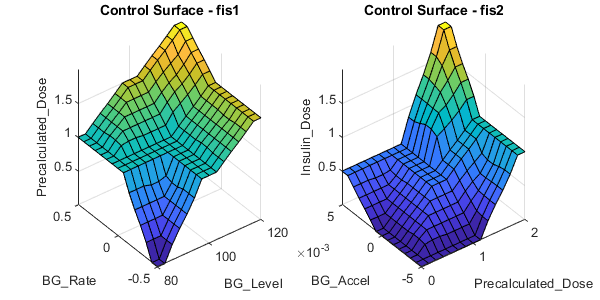

figure('Position',[300 300 600 300]);
subplot(1,2,1)
gensurf(fisTRuleUpdate.FIS(1))
title('Control Surface - fis1')
subplot(1,2,2)
gensurf(fisTRuleUpdate.FIS(2))
title('Control Surface - fis2')

Podemos simular con las nuevas reglas para ver si los resultados mejoran.

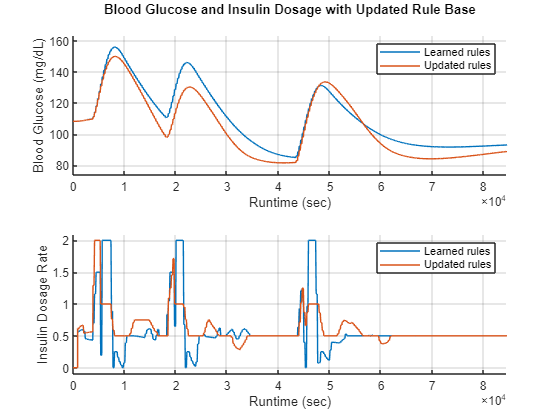

fisT = fisTRuleUpdate;
ruleUpdatedOutput = sim(model);

plotGlucoseAndInsulin([ruleTunedOutput ruleUpdatedOutput],...
    'Blood Glucose and Insulin Dosage with Updated Rule Base',...
    {'Learned rules','Updated rules'})

Para terminar de verificar que nuestro FIS con las reglas actualizadas presenta un mejor comportamiento, podemos obtener el costo de nuestro árbol difuso:

minCost = costFcn(fisTRuleUpdate,model,minLevel,refLevel,wsVars)

minCost = 23.2702

Como podemos observar, se redujo el costo actualizando las reglas.

### Optimización de las funciones de membresía

Como segundo paso optimizamos los parámetros de las funciones de membresía. Por defecto, las funciones de membresía son triangulares, observemos las forma de la primera entrada de `fis1`.

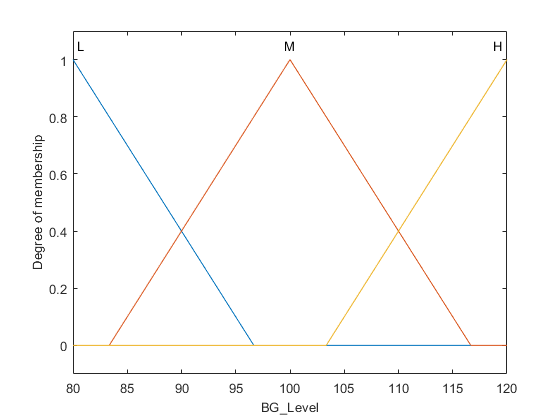

figure;
plotmf(fisTRuleUpdate.FIS(1),'input',1)

Podemos decir que las funciones `H` y `L` son adecuadas, ya que el máximo de ambas se encuentran en los límites de nuestro rango, por lo que las dejaremos intactas y sólo modificaremos la función `M`.

% Metodo de optimizacion
options.Method = 'patternsearch';
options.MethodOptions.MaxIterations = 10;

% Configuramos las MF para que la primera y ultima no puedan modificarse
% Entradas
for i = 1:4
    in(i).MembershipFunctions(1).Parameters.Free = [0 0 1];
    in(i).MembershipFunctions(end).Parameters.Free = [1 0 0];
end

% Salidas
for i = 1:2
    out(i).MembershipFunctions(1).Parameters.Free = [0 0 1];
    out(i).MembershipFunctions(end).Parameters.Free = [1 0 0];
end

% Si se quiere realizar la optimizacion ejecutar el siguiente codigo (puede
% tardar)

% figure
% reset(minData)
% rng('default')
% fisTMFTuned = tunefis(fisTRuleUpdate,[in;out],...
% @(fis)costFcn(fis,model,minLevel,refLevel,wsVars,minData),options);

% Importamos los datos ya entrenados
fisTMFTuned = data.fisTMFTuned;
% Obtenemos el costo de nuestro nuevo arbol difuso
minCost = costFcn(fisTMFTuned,model,minLevel,refLevel,wsVars)

minCost = 22.0627

Como podemos observar, disminuyó el costo al optimizar los parámetros de las funciones de membresía. Finalmente simulamos nuestro modelo.

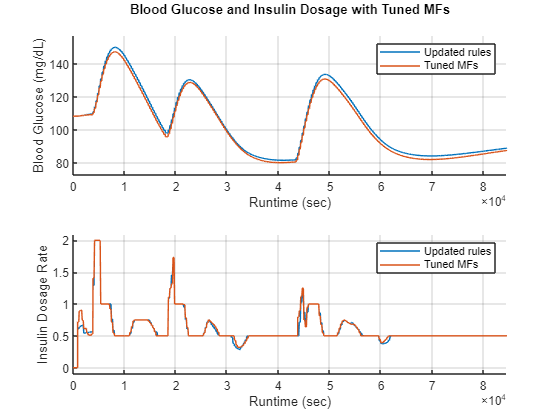

fisT = fisTMFTuned;
mfTunedOutput = sim(model);

plotGlucoseAndInsulin([ruleUpdatedOutput mfTunedOutput],...
    'Blood Glucose and Insulin Dosage with Tuned MFs',...
    {'Updated rules','Tuned MFs'})


% Cerramos el modelo
close_system(model)

## Funciones

### updateInput

function fis = updateInput(fis,id,name,range,mfNames)
    % Update FIS input with the specified parameter values.
    
    fis.Inputs(id).Name = name;
    fis.Inputs(id).Range = range;
    
    for mfId = 1:length(mfNames)
        fis.Inputs(id).MembershipFunctions(mfId).Name = mfNames(mfId);
        params = range(1) + ...
            diff(range)*fis.Inputs(id).MembershipFunctions(mfId).Parameters;
        fis.Inputs(id).MembershipFunctions(mfId).Parameters = params;
    end

end

function fis = updateOutput(fis,id,name,range)
% Update FIS output with the specified parameter values.

rangeDiff = diff(range);
fis.Outputs(id).Name = name;

% MF names - Very Low, Low, Medium, High, Very High
mfNames = [...
    "VL","L","M","H","VH"];

for mfId = 1:length(mfNames)
    fis.Outputs(id).MembershipFunctions(mfId).Name = mfNames(mfId);
    params = range(1) + ...
        rangeDiff*fis.Outputs(id).MembershipFunctions(mfId).Parameters;
    fis.Outputs(id).MembershipFunctions(mfId).Parameters = params;
end

% Extend output range values to fit the output MFs.
left = fis.Outputs(id).MembershipFunctions(1).Parameters(1);
right = fis.Outputs(id).MembershipFunctions(end).Parameters(end);
fis.Outputs(id).Range = [left right];

end